# Laboratory 2: Extended Euclidean Algorithm

%{
    Name:       NE
    Surname:    Ramashia
    StudentNo:  1490804
    Date:       04-May-2022
    Lab:        Extended Euclidean Algorithm
%}

## Part 1

[g,a,b] = Extended_Euclidean_Int (240, 46)

g = int32
2

a = int32
-9

b = int32
47

[g2,a2,b2] = gcd(240,46)

g2 = 2

a2 = -9

b2 = 47

% Testing the function with 100 sets of inputs

random_nums = randi([0 1000],100,2);
isWorking = true;
for i=1:100
 v = random_nums(i,1);
 u = random_nums(i,2);

 [g,a,b] = Extended_Euclidean_Int (v, u);
 [g2,a2,b2] = gcd(v,u);

 if(g~=g2 || a~=a2 || b~=b2)
     isWorking = false;
 end
end

if isWorking
 fprintf("It is Working");
else
 fprintf("It is NOT woring");
end

It is Working

The above tests shows that the implemented function generates the correct GCD as well the correct Bézout's identity coefficients.

## Part 2

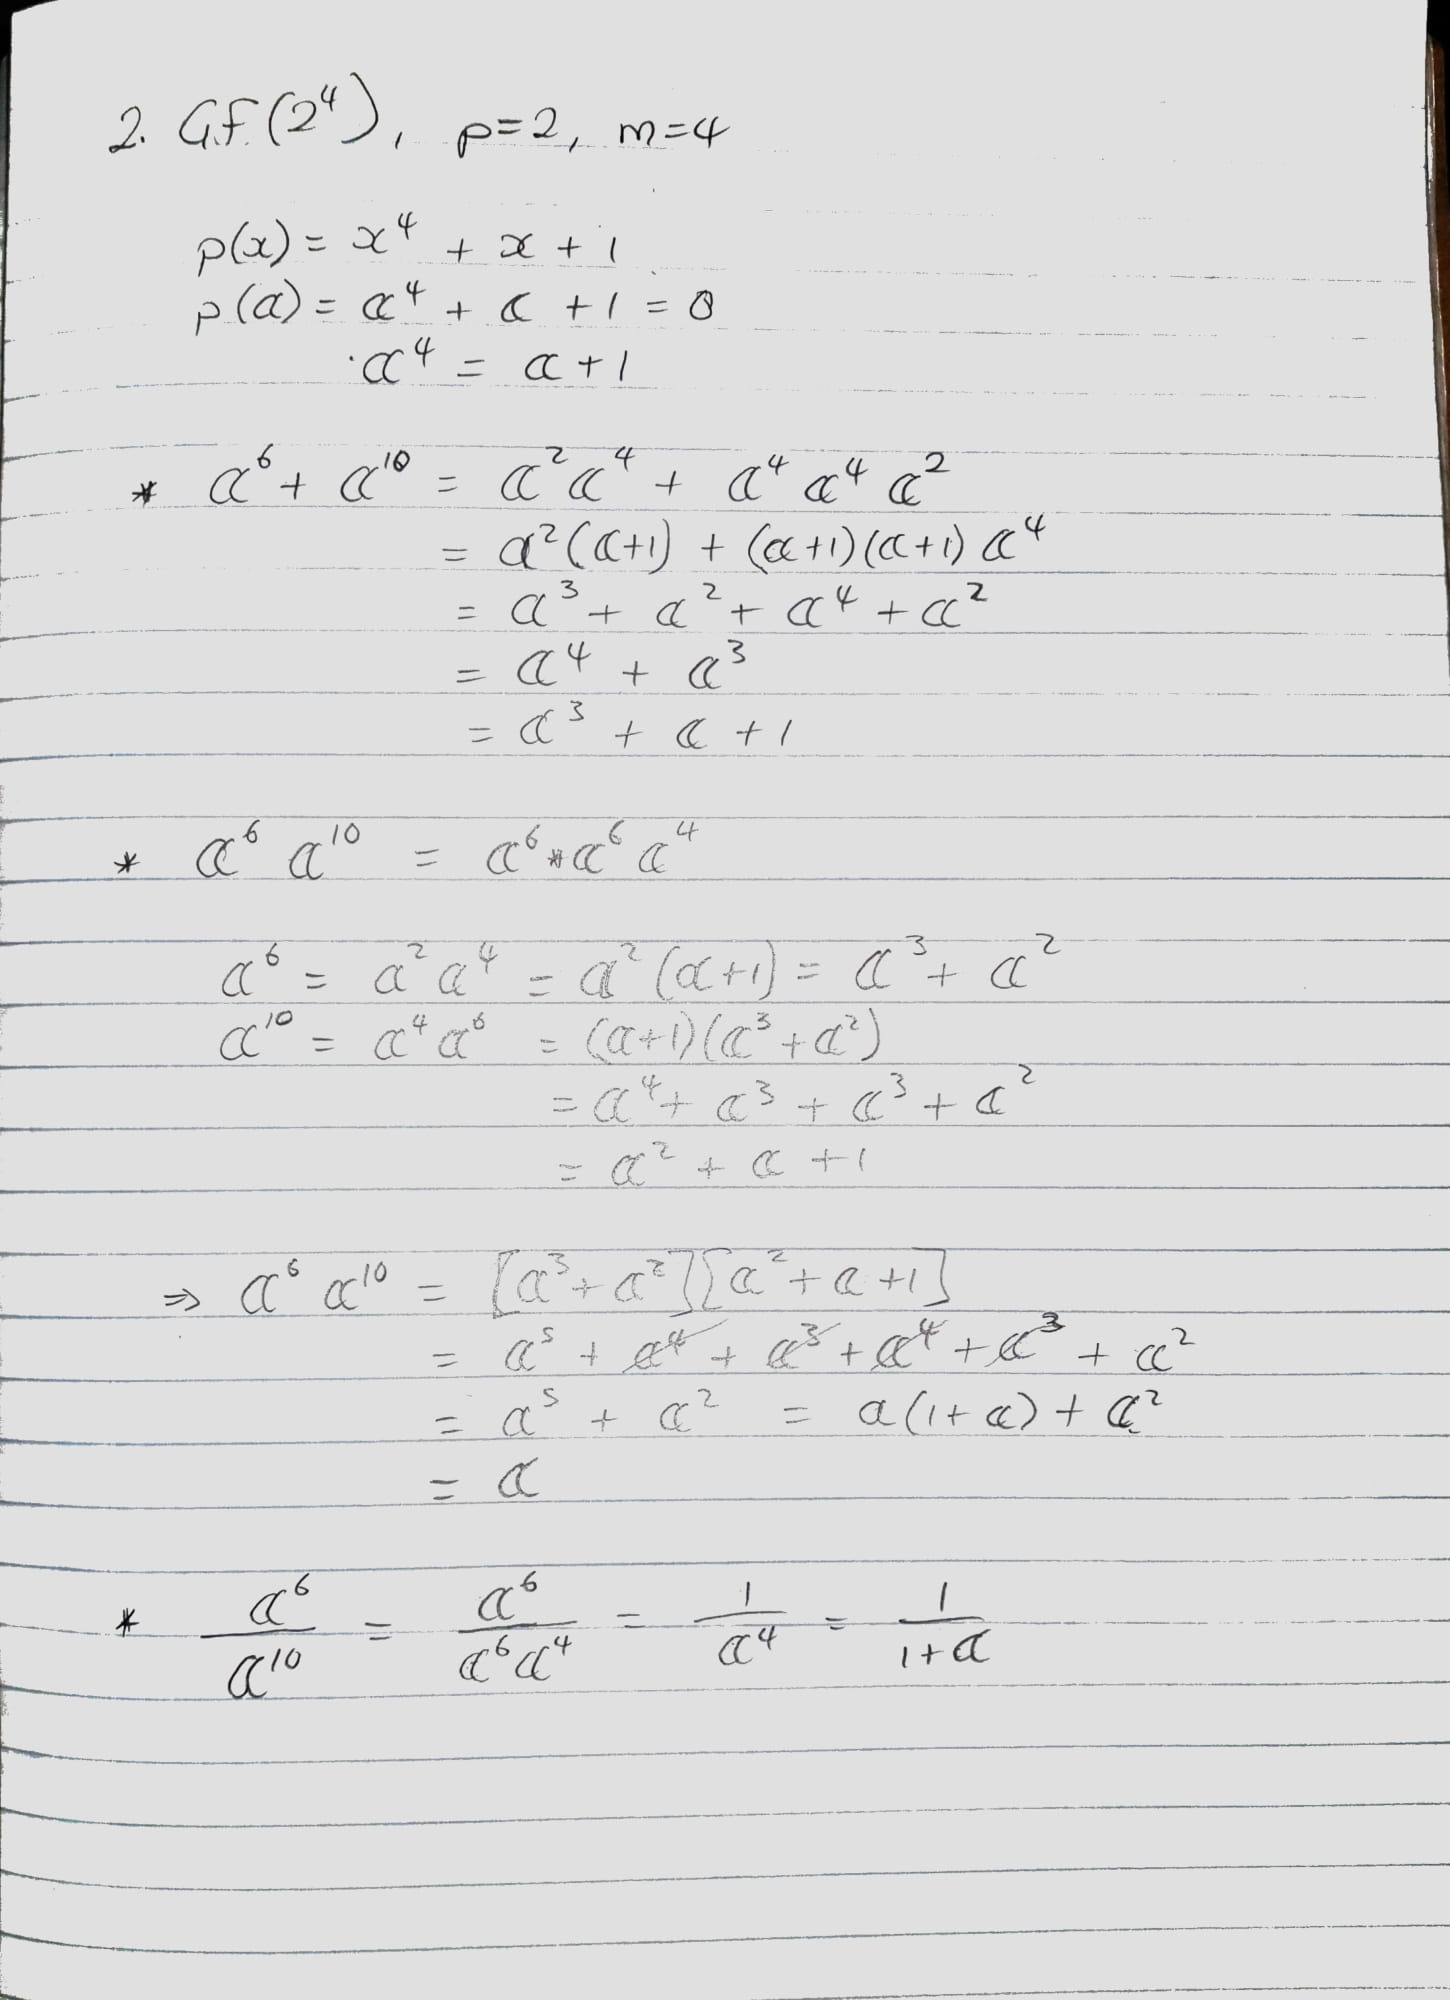

p = 2;
m = 4;
field = gftuple((-1:p^m-2)',m,p)

field =      0     0     0     0
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     1     1     0     0
     0     1     1     0
     0     0     1     1
     1     1     0     1
     1     0     1     0


sum = gfadd(6,10,field)

sum = 7

prod = gfmul(6,10,field)

prod = 1

quot = gfdiv(6,10,field)

quot = 11

## Part 3

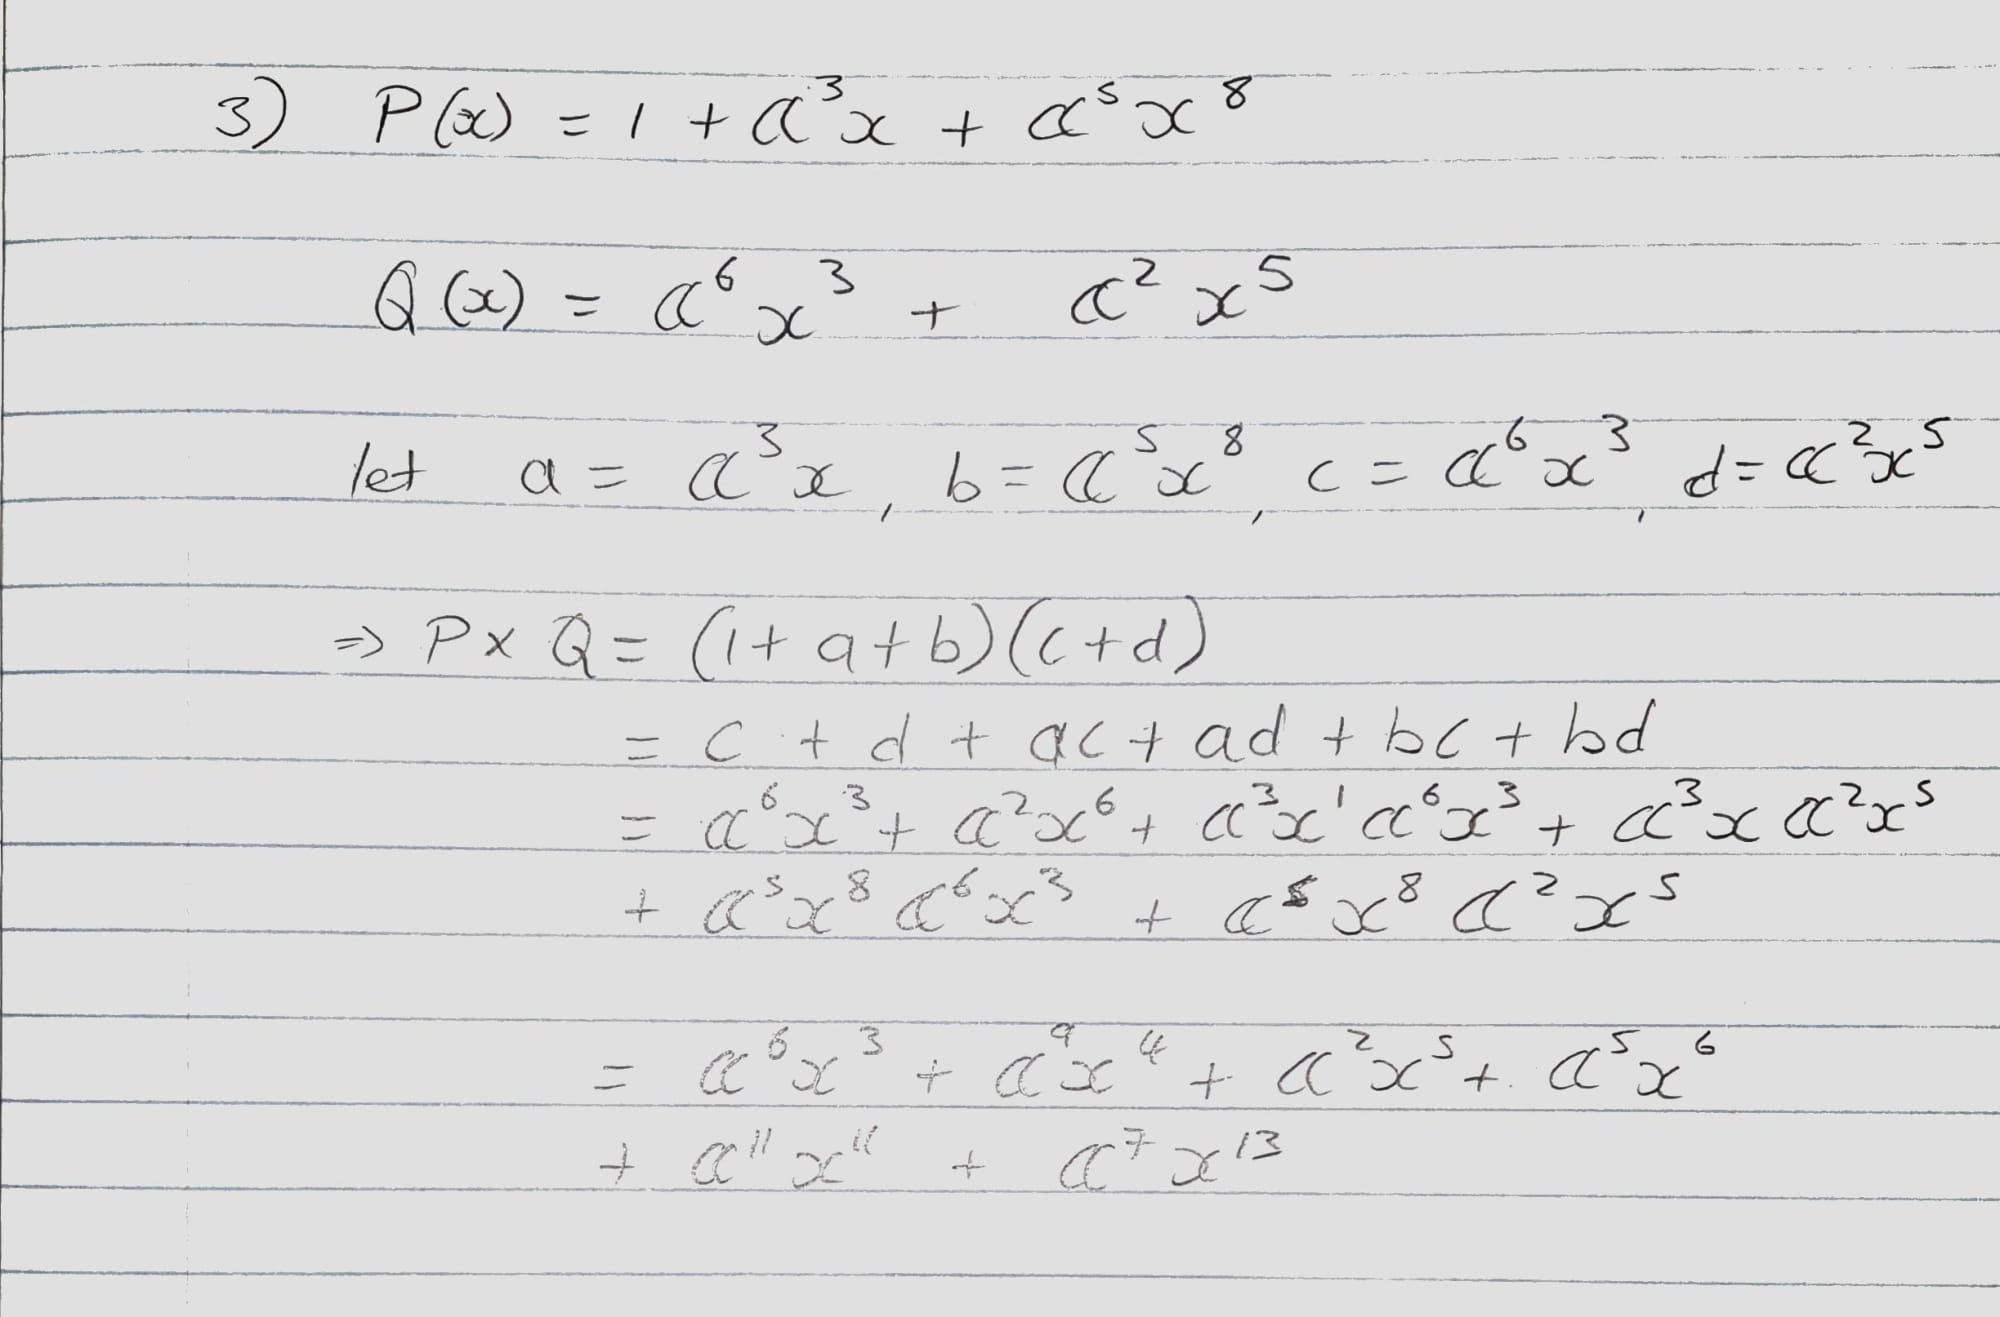

P3 = [1 3 -Inf -Inf -Inf -Inf -Inf -Inf 5];
Q3 = [-Inf -Inf -Inf 6 -Inf 2];
prod3 = gfconv(P3, Q3, field)

prod3 =   -Inf  -Inf  -Inf     7     9     3     5  -Inf  -Inf  -Inf  -Inf    11  -Inf     7


## Part 4

P4 = [0 -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf 0];
Q4 = [10 3 6 13 0];
[quotient4, remainder4] = gfdeconv(P4,Q4,field)

quotient4 =     11     6    10    13     3    10     1     1    13     0


remainder4 =     13     7     3    13


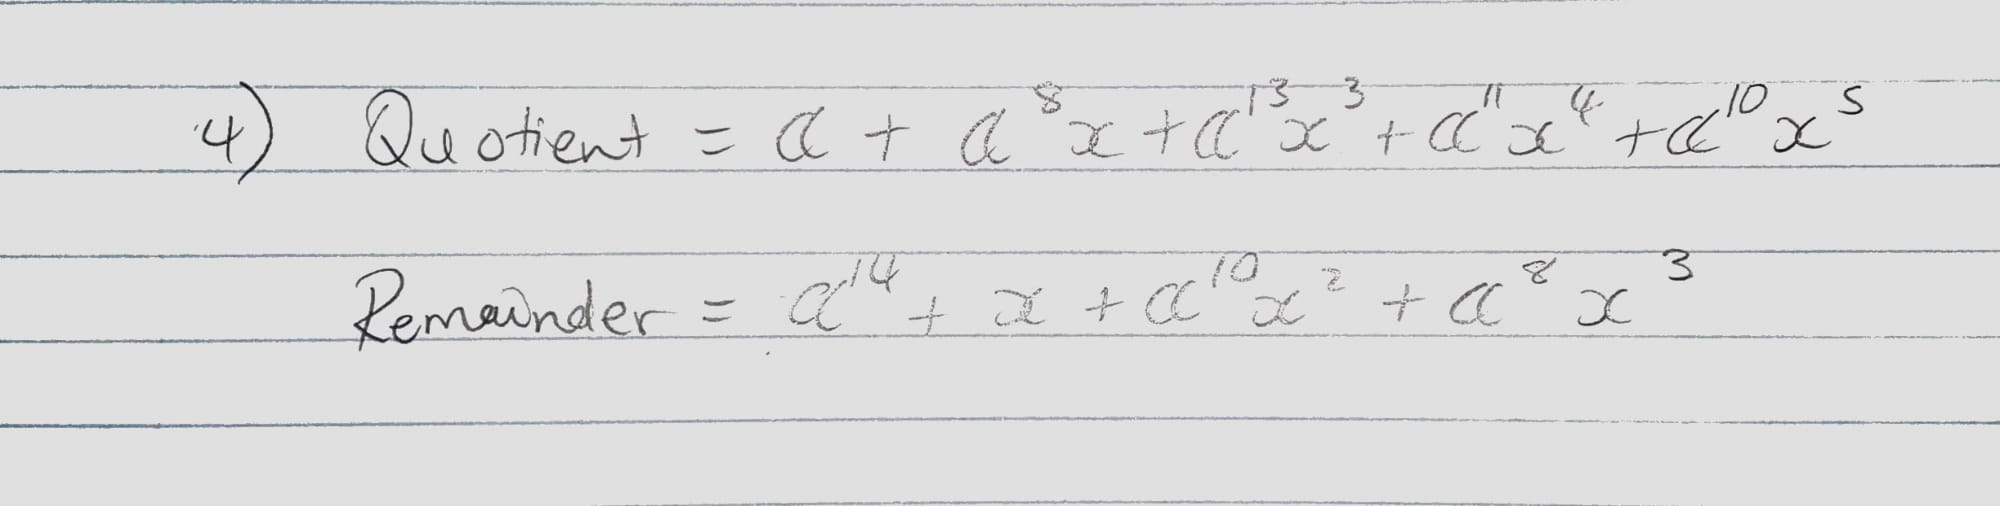

## Part 5

p=2;m=4;
field = gftuple((-1:p^m-2)',m,p);

A way to test the function "Extended_Euclidean_GF" was still to be successfully devised.